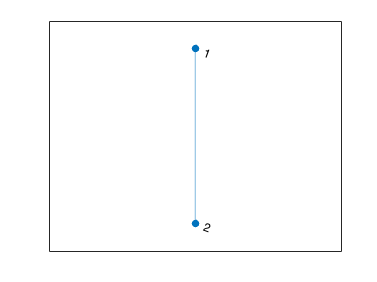

A= [0 1; 1 0];
G=graph(A);
plot(G);

L=[1 -1; -1 1];
eig(L);
[V,D,W]=eig(L)

V =    -0.7071   -0.7071
   -0.7071    0.7071


D =      0     0
     0     2


W =    -0.7071   -0.7071
   -0.7071    0.7071


% Adjacency matrix
A= [0 1; 1 0];
% Degree matrix
D= [1 0; 0 1]

D =      1     0
     0     1


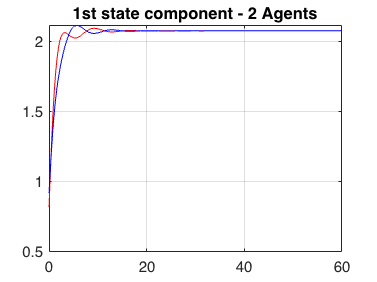

% Laplacian matrix= Degree-Adjacency 
L= D-A;

% Parameter constraints

% Number of agents
N = 2;

%% system

I=[1 0; 0 1];
Y=I;
E=[ 0 1 0; 0 0 1; 0 -2 -3];
%E=[ 0 1 0; 0 0 1; 0 -4 -6];
F=[ 0 0 0; 0 0 0; 1 0 0 ];
 
O=(kron(I,E))-(kron((Y*L),F));
V=ones(6,1);
W=eye(6);
X=0;
sys=ss(O,V,W,X);

%% 
x0=rand(6,1);
 
t = 0:0.01:60;
%u = max(0,min(t-1,1));
u=zeros(size(t));
 
[y,t,x]=lsim(sys, u, t, x0);

%% plot
figure;
plot(t,y(:,1),'r');
hold on
plot(t,y(:,4),'b');
grid on
title('1st state component - 2 Agents')
hold off

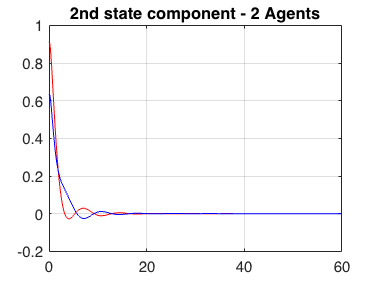

 
figure;
plot(t,y(:,2),'r');
hold on
plot(t,y(:,5),'b');
grid on
title('2nd state component - 2 Agents')
hold off

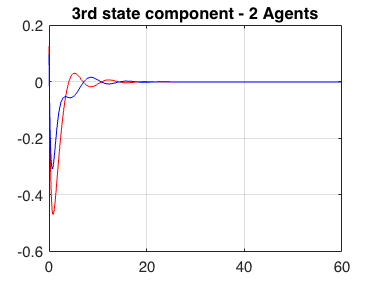

 
figure;
plot(t,y(:,3),'r');
hold on
plot(t,y(:,6),'b');
grid on
title('3rd state component - 2 Agents')
hold off

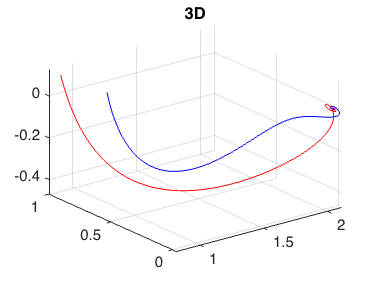


%%3Dplot

X1= [y(:,1)];
Y1= [y(:,2)];
Z1= [y(:,3)];
plot3(X1,Y1,Z1,'r');
hold on
X2= [y(:,4)];
Y2= [y(:,5)];
Z2= [y(:,6)];
plot3(X2,Y2,Z2,'b');
grid on
title ('3D')
hold off